## [AdaBoost Classification](https://apmonitor.com/pds/index.php/Main/AdaBoost)

AdaBoost (Adaptive Boosting) is a machine learning algorithm for classification. It is a type of ensemble learning algorithm that is used to improve the accuracy of a model by combining the predictions of multiple weaker models.

The algorithm works by iteratively training a series of weak models on subsets of the data, with each model attempting to correct the mistakes of the previous model. At each iteration, the weights of the incorrectly predicted examples are increased, so that the next model is more likely to focus on the examples that were misclassified by the previous models. It is used as a supervisory layer to other classification algorithms such as neural networks, decisions trees, and support vector machines. It takes weak classifiers as a weighted sum and adaptively refines the output to focus on the harder-to-classify cases.

In this example, we first create a decision tree classifier with a maximum depth of 1 as the base model for AdaBoost. Then, we train an AdaBoost classifier using the decision tree as the base model and 100 estimators. Finally, we use the trained model to make predictions on the test set.

**Optical Character Recognition with AdaBoost**

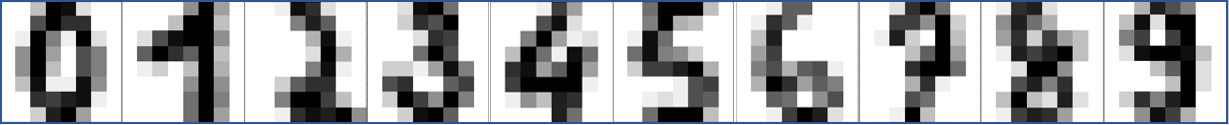

Optical character recognition (OCR) is the process of extracting text from images or scanned documents. OCR algorithms are typically based on machine learning models that are trained on large datasets of images containing text.

Dataset: [Data Sets for Deep Learning - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/deeplearning/ug/data-sets-for-deep-learning.html)

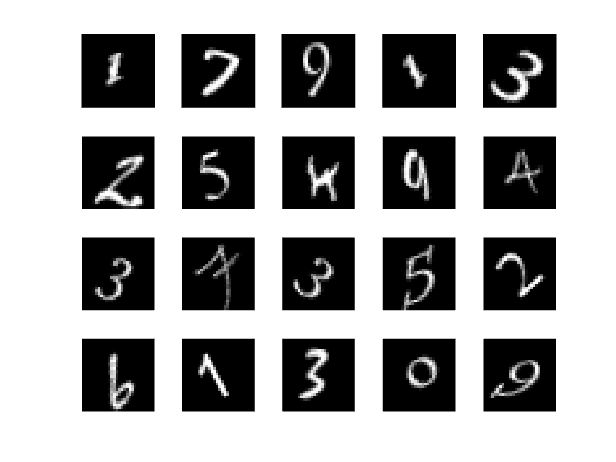

% Import dataset of numbers
digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
    'nndatasets','DigitDataset');
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');

% Show example of dataset
figure;
perm = randperm(10000,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

n_samples = length(imds.Files);

% Extract the images into a matrix
X_data = [];
for i = 1:n_samples
    X_data = [X_data; reshape(readimage(imds,i)',[1,28*28])];
end

% Save the labels of the images
Y_data = imds.Labels(1:n_samples);

% Split the data 50% training adn 50% testing
[trainInd,valInd,testInd] = dividerand(n_samples,0.5,0,0.5);

X_Train = X_data(trainInd,:);
X_Test = X_data(testInd,:);
Y_Train = Y_data(trainInd,:);
Y_Test = Y_data(testInd,:);

% Create fit
classifier = fitcensemble(array2table(im2double(X_Train)),Y_Train,'Method','AdaBoostM2');

% Evaluate the model performance on the test set
y_pred = predict(classifier,array2table(im2double(X_Test)));
accuracy = mean(y_pred == Y_Test);
fprintf("Accuracy: %.2f\n", accuracy);

Accuracy: 0.64


The accuracy is okay for this particular example (~63%). Further tuning of the options would increase the accuracy. Below is an example that also shows a number from the test set that is evaluated with the AdaBoost classifier.

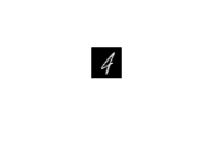

tbl = [array2table(im2double(X_Train)), array2table(Y_Train)];

% Select random nummber image
n = randi([0,n_samples],1);
figure;
imshow(imds.Files{n})

reshape(readimage(imds,n)',[1,28*28]);

% Predict number based on image
yp = predict(classifier,im2double(reshape(readimage(imds,n)',[1,28*28])));
disp(['Predicted:',yp])

     Predicted:      4 

